#### 1. Função de Transferência do sistema

clearvars;
a = 14.97;
s = tf('s');
K = 750;
Gp = a * K /(s+a);
Gp_zpk = zpk(Gp)

Gp_zpk =
 
    11228
  ---------
  (s+14.97)
 
Continuous-time zero/pole/gain model.
Model Properties


#### 2. Modelo em espaço de estado


$$\dot{\mathbf{x}}(t) = \mathbf{A}\mathbf{x}(t) + \mathbf{B}\mathbf{u}(t) \\
\mathbf{y}(t) = \mathbf{C}\mathbf{x}(t) + \mathbf{D}\mathbf{u}(t)
$$


[num, den] = tfdata(Gp, 'v'); 
[Ac, Bc, Cc, Dc] = tf2ss(num, den)

Ac = -14.9700

Bc = 1

Cc = 1.1228e+04

Dc = 0

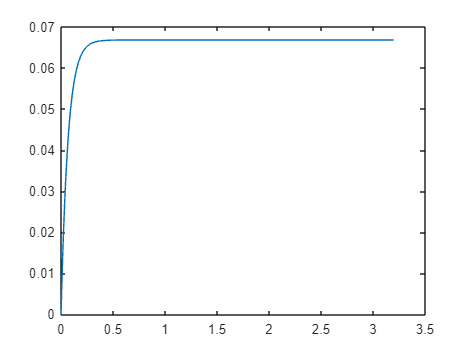


t = 0:400;
t = t*8*10^(-3);

[y, x, t] = step(Ac, Bc, Cc, Dc, 1, t);

figure;
plot(t,x);

#### 3. Discretização das equações de estado


$$\mathbf{x}[k+1] = \mathbf{A}_d \, \mathbf{x}[k] + \mathbf{B}_d \, \mathbf{u}[k] \\
\mathbf{y}[k] = \mathbf{C}_d \, \mathbf{x}[k]
$$


Ts = 0.008; % Período de amostragem (Ts = 8ms)
sys = ss(Ac, Bc, Cc,[]); % Sistema tempo contínuo
sysd = c2d(sys,Ts,'zoh');

Ad = sysd.A

Ad = 0.8871

Bd = sysd.B

Bd = 0.0075

Cd = sysd.C

Cd = 1.1228e+04

#### 4.  Projetando o Controlador

**4.1 Avaliando Controlabilidade e Observabilidade**

% Controlabilidade

Sz = [Bd];

if length(Sz)==1
    if Sz~=0
        fprintf("É controlável.");
    else
        fprintf("Não é controlável.");
    end
else
    if det(Sz)~=0
        fprintf("É controlável.");
    else
        fprintf("Não é controlável.");
    end
end

É controlável.


% Convertendo para FCC

Q1_c = [1] * Sz^(-1);

Q_c = [Q1_c];

Ax_fcc = Q_c*Ad*Q_c^(-1)

Ax_fcc = 0.8871

Bx_fcc = Q_c*Bd

Bx_fcc = 1

Cx_fcc = Cd*Q_c^(-1)

Cx_fcc = 84.6500


Sx = [Bx_fcc];

P_c = Sz*Sx^(-1);

% Observabilidade

Vz = [Cd];

if length(Vz)==1
    if Vz~=0
        fprintf("É observável.");
    else
        fprintf("Não é observável.");
    end
else
    if det(Vz)~=0
        fprintf("É observável.");
    else
        fprintf("Não é observável.");
    end
end

É observável.


% Convertendo para FCO

Q1_o = [Cd]^(-1) * [1];

Q_1_o = [Q1_o];

Q_o = Q_1_o^(-1);

Ax_fco = Q_o*Ad*Q_1_o

Ax_fco = 0.8871

Bx_fco = Q_o*Bd

Bx_fco = 84.6500

Cx_fco = [1]

Cx_fco = 1


Vx = [Cx_fco];

P_o = Vz^(-1)*Vx;

**4.2 Definindo Especificações de Desempenho **

% Polos desejados
cf = 700;
cmax = 800;

% Ultrapassagem percentual.
Up = ((cmax-cf)/cf) * 100 

Up = 14.2857


% Tempo de acomodação.
Ts = 1.5 ;

qsi = (-log(Up/100))/(sqrt(pi^2+log(Up/100)^2));

% Calcula o fator de amortecimento
% requerido.

wn = 4/(qsi*Ts); % Calcula a frequência natural
% requerida.

[numd,dend] = ord2(wn,qsi); % Produz um sistema de
% segunda ordem que atende aos
% requisitos de resposta transitória.

r = roots(dend); % Usa o denominador para
% especificar os polos dominantes.

polos = [r(1) r(2)] % Especifica a posição de todos

polos =   -2.6667 + 4.3052i  -2.6667 - 4.3052i


% os polos.

eq_caracteristica_desejada = poly(polos);

fprintf('Equação característica desejada:\n');

Equação característica desejada:


fprintf('s^2 + %.2fs + %.2f\n', ...
    eq_caracteristica_desejada(2), ...
    eq_caracteristica_desejada(3));

s^2 + 5.33s + 25.65


**4.3 Adicionando Ação Integral**

% Construção do sistema aumentado
A_hat = [Ac     zeros(size(Ac,1),1);
         -Cc     0]

A_hat = 1.0e+04 *

   -0.0015         0
   -1.1227         0



B_hat = [Bc;
         0]

B_hat =      1
     0



C_hat = [Cc 0]

C_hat = 1.0e+04 *

    1.1227         0



% Polos desejados (reutilizados ou altere para adicionar um terceiro)
% Adicionando um polo extra mais à esquerda para o integrador


% Projeto do ganho com realimentação de estados aumentados
K_hat = acker(A_hat, B_hat, polos);

% Extração dos ganhos K e Ki
K  = K_hat(1:end-1)

K = -9.6367

Ki = -K_hat(end)

Ki = 0.0023


% Sistema em malha fechada com integrador
A_hat_cl = [Ac - Bc*K, Bc*Ki;
            -Cc      ,  0];

B_hat_cl = [0; 1];  % Entrada de referência
C_hat_cl = [Cc 0];
D_hat_cl = 0;

sys_ss = ss(A_hat_cl, B_hat_cl, C_hat_cl, D_hat_cl);
sys_tf = tf(sys_ss);  % Converte espaço de estados para FT

[y, tOut] = step(sys_tf, t);

zpk(sys_tf)           % Exibe zeros, polos e ganho

ans =
 
          25.646
  ----------------------
  (s^2 + 5.333s + 25.65)
 
Continuous-time zero/pole/gain model.
Model Properties


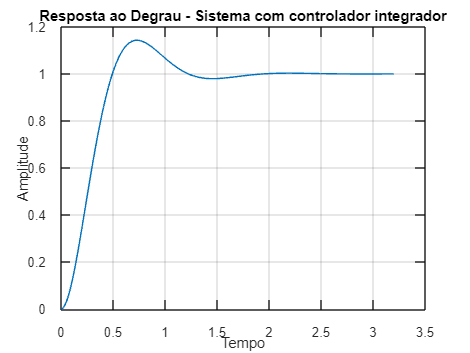


% Plotagem dos estados
figure;
plot(tOut, y);
title('Resposta ao Degrau - Sistema com controlador integrador');
ylabel('Amplitude');
xlabel('Tempo');
grid on;

**4.4  Análise das EDS**

info = stepinfo(y, tOut);

% Tempo de acomodação a 2%
Ts = info.SettlingTime;
Tr = info.RiseTime;
Tp= info.PeakTime;
UP= info.Overshoot;
fprintf('Tempo de subida : %.4f ms\n', Tr);

Tempo de subida : 0.3338 ms


fprintf('Tempo de acomodação: %.4f ms\n', Ts);

Tempo de acomodação: 1.4896 ms


fprintf('Tempo de pico : %.4f ms\n', Tp);

Tempo de pico : 0.7280 ms


fprintf('Ultrapassagem percentual : %.4f ms\n', UP);

Ultrapassagem percentual : 14.3061 ms


### **5. Projetando o Observador**

#### **5.1 Equação caracteristica desejada do observador**

**(Ts 10x menor do que o do controlar)**

Ts_obs = (Ts / 10);
wn_obs = 4/(qsi*Ts_obs); % Calcula a frequência natural

polos_o =  -26.8521 +43.3516i -26.8521 -43.3516i


Equação característica desejada:


s^2 + 53.70s + 2600.39



polo_o = qsi*wn_obs

polo_o = 26.8521

Codigo do nise p projetar observador na fco

Matriz' = Transposta conjugada 

L = place(Ac', Cc', polo_o)'

L = -0.0037


Ao = Ac-Bc*K - L*Cc   

Ao = 36.4887

Bo = L

Bo = -0.0037

Co = K

Co = -9.6367

Do = 0

Do = 0


sys_ss_o = ss(Ao, Bo, Co, Do);
sys_tf_o = tf(sys_ss_o);  % Converte espaço de estados para FT

[y_o, tOut_o] = step(sys_tf_o, t);

zpk(sys_tf)           % Exibe zeros, polos e ganho

ans =
 
          25.646
  ----------------------
  (s^2 + 5.333s + 25.65)
 
Continuous-time zero/pole/gain model.
Model Properties



figure;
plot(tOut_o, y_o);
title('Resposta ao Degrau - Sistema com observador');
ylabel('Amplitude');
xlabel('Tempo');
grid on;
